# Cart under weak chaotic shaking

 The system is shown pictorially :

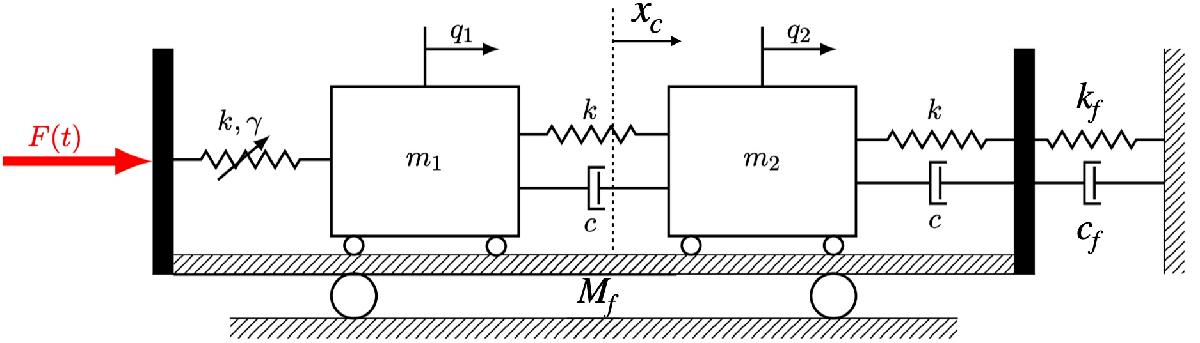

The forcing is easier to express when one moves to the center of mass coordinates and the relative displacement coordinates of the smaller blocks. Further we shift the centre of mass coordinates to make the origin the fixed point. In these coordinates the mechanical system is written as 


$$\mathbf{{M}}=\left(\begin{array}{ccc}
M_{f}\frac{(m_{1}+m_{2})}{M_{T}} & \frac{m_{2}M_{f}}{M_{T}} & 0\\
\frac{m_{2}M_{f}}{M_{T}} & m_{2}\frac{(m_{1}+M_{f})}{M_{T}} & 0\\
0 & 0 & M_{T}
\end{array}\right),\quad{K}=\left(\begin{array}{ccc}
2k+\frac{k_{f}(m_{1}+m_{2})^{2}}{M_{T}^{2}} & k+\frac{k_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & -k_{f}\frac{m_{1}+m_{2}}{M_{T}}\\
k+\frac{k_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & 2k+\frac{k_{f}m_{2}^{2}}{M_{T}^{2}} & -k_{f}\frac{m_{2}}{M_{T}}\\
-k_{f}\frac{m_{1}+m_{2}}{M_{T}} & -k_{f}\frac{m_{2}}{M_{T}} & k_{f}
\end{array}\right),$$


${C}=\left(\begin{array}{ccc}
c+\frac{k_{f}(m_{1}+m_{2})^{2}}{M_{T}^{2}} & c+\frac{c_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & -c_{f}\frac{m_{1}+m_{2}}{M_{T}}\\
c+\frac{c_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & 2c+\frac{c_{f}m_{2}^{2}}{M_{T}^{2}} & -c_{f}\frac{m_{2}}{M_{T}}\\
-c_{f}\frac{m_{1}+m_{2}}{M_{T}} & -c_{f}\frac{m_{2}}{M_{T}} & c_{f}
\end{array}\right),\quad f(\mathbf{{x},\dot{{x}}})=\left(\begin{array}{c}
\gamma q_{1}^{3}\\
0\\
0
\end{array}\right) \quad \text{{and}\quad}\mathbf{{F}(t)}=\left(\begin{array}{c}
0\\
0\\
M_{T}g(t)
\end{array}\right)$.

where $M_{T}=M_{f}+m_{1}+m_{2}$ and ${x}=\left(\begin{array}{c}
q_{1}\\
q_{2}\\
x_{c}
\end{array}\right)$. The autonomous system is got from the Euler-Lagrange equations of the Lagrangian and Rayleigh dissipation function given by


$$L=T+V$$



$$T=\frac{1}{2}M_{f}\dot{x}_{f}^{2}+\frac{1}{2}m_{1}\dot{x}_{1}^{2}+\frac{1}{2}m_{2}\dot{x}_{2}^{2}$$



$$V=\frac{1}{2}kq_{1}^{2}+\frac{1}{2}kq_{2}^{2}+\frac{1}{2}k(L_{2}+L_{1}-3l_{0}-q_{1}-q_{2})^{2}+\frac{1}{4}\gamma q_{1}^{4}+\frac{1}{2}k_{f}(\Lambda-L_{2}-l_{0}-x_{f})^{2}$$



$$R=\frac{1}{2}c\dot{q}_{2}^{2}+\frac{1}{2}c(\dot{q}_{1}+\dot{q}_{2})^{2}+\frac{1}{2}c_{f}\dot{x_{f}}^{2}$$


where $q_{1}=x_{1}-(x_{F}-L_{1})-l_{0}$, $q_{2}=x_{2}-x_{1}-l_{0}$ and $x_{c}=\frac{M_{f}x_{f}+m_{1}x_{1}+m_{2}x_{2}}{M_{f}+m_{1}+m_{2}}-d_{0}$. $L_{1}+L_{2}$ is the length of the cart, $l_{0}$ natural length of the spring and $\Lambda$is the distance of the wall from the user reference frame. Since we assume the block masses are point masses we have $L_{1}+L_{2}=3l_{0}$. The length $d_{0}$ represents the equilibrium position of the centre of mass from the user reference frame, subtracting this from the centre of mass gives the shifted coordinate $x_{c}$. From the free body diagram of the cart the forcing acts on the centre of mass coordinate of the cart, hence appears as a collective shaking force that influences all the degrees of the freedom of the cart.

The signal $g(t)$ is generated using the initial condition $[0,0.3,0.5]$. The system paramters and forcing are generated below: 

clear all

m1 = 1;
m2 = 1;
Mf = 4;
kf = 1;
k = 1;
c = 0.3;
cf = 0.3;
gamma = 0.5;
MTT = m1 + m2 + Mf;
K = -[-2*k - kf*((m1 + m2)/MTT)^2, -k - kf*m2*(m1 + m2)/MTT^2, kf*(m1+m2)/MTT; -k - kf*m2*(m1 + m2)/MTT^2, -2*k - kf*m2^2/(MTT^2), kf*m2/MTT; (m1 + m2)/MTT *kf, m2/MTT*kf, -kf];
C = -[-c - cf*((m1 + m2)/MTT)^2, -c - cf*m2*(m1 + m2)/MTT^2, cf*(m1+m2)/MTT; -c - cf*m2*(m1 + m2)/MTT^2, -2*c - cf*m2^2/(MTT^2), cf*m2/MTT; (m1 + m2)/MTT *cf, m2/MTT*cf, -cf];
M =  [Mf*(m1 + m2)/MTT, m2*Mf/MTT, 0; m2*Mf/MTT, m2*(m1 + Mf)/MTT, 0; 0,0, MTT];

A = [zeros(3),eye(3);inv(M)*K,inv(M)*C];

subs2 = [1 1 1 1];
n = 3;
F3 = sptensor(subs2, gamma, [n,n,n,n]);
F2 = sptensor([n,n,n]);
fnl = {F2,F3};


n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 3


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 6



%%
% DS set up - SSM tool
hold on
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',6,'Nmax',10,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 nonzero eigenvalues are given as 
  -0.0228 + 0.3956i
  -0.0228 - 0.3956i
  -0.1234 + 1.2699i
  -0.1234 - 1.2699i
  -0.3788 + 1.6707i
  -0.3788 - 1.6707i



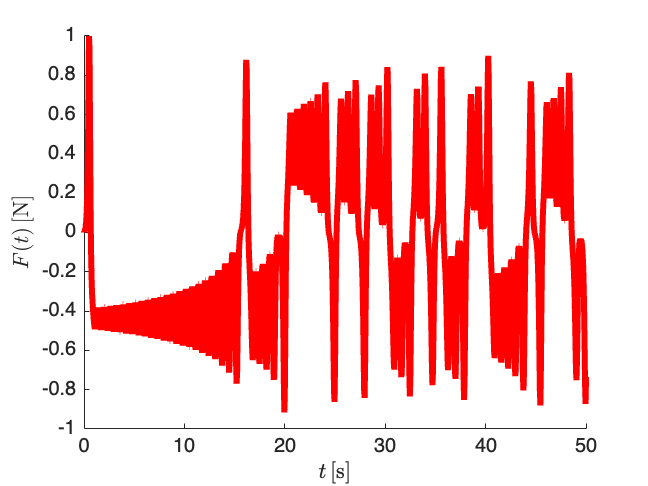

S = SSM(DS);
resonant_modes = [1 2];
Acheck = V*diag(D)*inv(V);
VI = inv(V);



%Lorenz force 
%%

L = 0;
%L = -5000;
N_Max = 10000;
tspan = linspace(L,500,N_Max);
loren = @(t,y) lorenz_3D(t,y);
IC = [0;0.3;0.5];
[tk,yy] = ode45(loren,tspan,IC);

sigma = 10;
rho = 28;
beta = 8/3;

% F_a = -(sigma*rho*yy(:,1) - sigma*yy(:,1).*yy(:,3) - sigma*yy(:,2) - sigma^2*yy(:,2) + sigma^2*yy(:,1));
F_a_new = yy(:,1)/max(abs(yy(:,1)));


Force_Lorenz = griddedInterpolant(tspan(:),F_a_new(:),'spline');




plot(tk,F_a_new,'-','LineWidth',3,'Color','red')
xlabel('$t \,[$s$]$','Interpreter','latex');
ylabel('$F(t) \,[$N$]$','Interpreter','latex');
axis([0 50 -1 1])

The anchor trajectory is calculated to O(5). The non-zero anchor trajectory at various orders are saved. If you wish to recompute these please set flag to 1. 

flag =0;
% order epsilon solution
% AP = [0,0,1,0;0,0,0,1;-2*k,k,-c,c;k,-2*k,c,-2*c];
if flag == 1

%%
xs=@(t,ta) real(V*([exp(D(1)*(t-ta));conj(exp(D(1)*(t-ta)));exp(D(3)*(t-ta));conj(exp(D(3)*(t-ta)));exp(D(5)*(t-ta));conj(exp(D(5)*(t-ta)))].*(VI*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));Force_Lorenz(ta)])));
% positive_Lvec = find(tspan<-3999 & tspan>-4000);
% positive_L = positive_Lvec(1)-1;
positive_L = 1;

tcalc = tspan(positive_L:end);
N_Max = max(size(tcalc));
LT = [];
 start_time = [1];
xi_sol = cell(1,max(size(start_time)));

tic
sol_1 = [];
parfor i = 1:max(size(tcalc))
Lo = positive_L - 1 + i ;
T = tspan(start_time(1):Lo);
ti = tcalc(i);

INx = xs(ti,T);

Q1x = trapz(T,INx,2);
sol_1  =[sol_1,Q1x];
end    
xi_sol{1,1} = sol_1;
LT = [LT,tspan(start_time(1))];
toc
 start_time=positive_L;
xi_solg=sol_1.'; 
xi_full = griddedInterpolant(tcalc(:),xi_solg,'spline');
xi_full_eval = @(xa) xi_full(xa);
save('Solution_1.mat','xi_full_eval')

xi_sol0=xi_sol{1,1};
xi_sol1 = griddedInterpolant(tcalc(:),(xi_sol0(1,:)).','spline');
% xi_sol2 = @(xq) interp1(tcalc(:),(xi_sol0(2,:)).',xq,'spline');
% xi_sol3 = @(xq) interp1(tcalc(:),(xi_sol0(3,:)).',xq,'spline');
% xi_sol4 = @(xq) interp1(tcalc(:),(xi_sol0(4,:)).',xq,'spline');
% xi_net_sol = @(t) [xi_sol1(t);xi_sol2(t);xi_sol3(t);xi_sol4(t)];
save('Xi_Sol1.mat','xi_sol1')


xs=@(t,ta) real(V*([exp(D(1)*(t-ta));conj(exp(D(1)*(t-ta)));exp(D(3)*(t-ta));conj(exp(D(3)*(t-ta)));exp(D(5)*(t-ta));conj(exp(D(5)*(t-ta)))].*(VI*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));-(m1+Mf)/(m1*Mf)*gamma*xi_sol1(ta).^3;1/m1*gamma*xi_sol1(ta).^3;0*ones(1,max(size(ta)))])));
% positive_Lvec = find(tspan<-2999 & tspan>-3000);
% positive_L = positive_Lvec(1)-1;
positive_L = 1;

tcalc = tspan(positive_L:end);
N_Max = max(size(tcalc));
LT = [];

xi_sol = cell(1,max(size(start_time)));

tic
sol_1 = [];
parfor i = 1:max(size(tcalc))
Lo = positive_L - 1 + i ;
T = tspan(start_time:Lo);
ti = tcalc(i);

INx = xs(ti,T);

Q1x = trapz(T,INx,2);
sol_1  =[sol_1,Q1x];
end    
xi_sol{1,1} = sol_1;
LT = [LT,tspan(start_time(1))];
toc

xi_solg=sol_1.'; 
xi_full = griddedInterpolant(tcalc(:),xi_solg,'spline');
xi_full_eval3 = @(xa) xi_full(xa);
save('Solution_3.mat','xi_full_eval3')

xi_sol0=xi_sol{1,1};
xi_sol3 = griddedInterpolant(tcalc(:),(xi_sol0(1,:)).','spline');
save('Xi_Sol3.mat','xi_sol3')



xs=@(t,ta) real(V*([exp(D(1)*(t-ta));conj(exp(D(1)*(t-ta)));exp(D(3)*(t-ta));conj(exp(D(3)*(t-ta)));exp(D(5)*(t-ta));conj(exp(D(5)*(t-ta)))].*(VI*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));3*-(m1+Mf)/(m1*Mf)*gamma*xi_sol1(ta).^2.*xi_sol3(ta);3*1/m1*gamma*xi_sol1(ta).^2.*xi_sol3(ta);0*ones(1,max(size(ta)))])));
% positive_Lvec = find(tspan<-2999 & tspan>-3000);
% positive_L = positive_Lvec(1)-1;
positive_L = 1;

tcalc = tspan(positive_L:end);
N_Max = max(size(tcalc));
LT = [];

xi_sol = cell(1,max(size(start_time)));

tic
sol_1 = [];
parfor i = 1:max(size(tcalc))
Lo = positive_L - 1 + i ;
T = tspan(start_time:Lo);
ti = tcalc(i);

INx = xs(ti,T);

Q1x = trapz(T,INx,2);
sol_1  =[sol_1,Q1x];
end    
xi_sol{1,1} = sol_1;
LT = [LT,tspan(start_time(1))];
toc

xi_solg=sol_1.'; 
xi_full = griddedInterpolant(tcalc(:),xi_solg,'spline');
xi_full_eval5 = @(xa) xi_full(xa);
save('Solution_5.mat','xi_full_eval5')
end

Elapsed time is 14.586737 seconds.


Elapsed time is 15.133186 seconds.


Elapsed time is 12.756522 seconds.


Now we calculate the non-autonomous SSM coefficients upto this order by solving the invariance PDE. 

load('Xi_Sol1.mat','xi_sol1')
load('Solution_3.mat','xi_full_eval3')
load('Solution_1.mat','xi_full_eval')
load('Solution_5.mat','xi_full_eval5')
load('Xi_Sol3.mat','xi_sol3')
l1 = D(1);
l1c = conj(D(1));
l2 = D(3);
l2c = conj(D(3));
l3 = D(5);
l3c = conj(D(5));


[h030,h120,h210,h300,f030,f120,f210,f300,hc030,hc120,hc210 ...
    ,hc300,fc030,fc120,fc210,fc300,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,hc500,hc050,hc320,hc230,hc410,hc140,fc500,fc050,fc320,fc230,fc410,fc140...
    ] = Auto_Coeffs(gamma,l2,l3,l1c,l1);

start_time = [1];

if flag == 1

%%
h_coeff = @(t,ta) H_coeff_1(t,ta,gamma,l1,l2,l3,l1c,h030,h120,h210,h300,f030,f120,f210,f300,hc030,hc120,hc210 ...
    ,hc300,fc030,fc120,fc210,fc300,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,hc500,hc050,hc320,hc230,hc410,hc140,fc500,fc050,fc320,fc230,fc410,fc140...
    ,xi_sol1,xi_sol3);


f_coeff = @(t,ta) F_coeff_1(t,ta,gamma,l1,l2,l3,l1c,h030,h120,h210,h300,f030,f120,f210,f300,hc030,hc120,hc210 ...
    ,hc300,fc030,fc120,fc210,fc300,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,hc500,hc050,hc320,hc230,hc410,hc140,fc500,fc050,fc320,fc230,fc410,fc140...
    ,xi_sol1,xi_sol3);


positive_L = 1;
tcalc = tspan(1:end);
N_Max = max(size(tcalc));
sol_1rH = [];
sol_1iH = [];

sol_1rF = [];
sol_1iF = [];

tic
for i = 1:max(size(tcalc))
Lo = positive_L - 1 + i ;
T = tspan(start_time(1):Lo);
ti = tcalc(i);

INxH = h_coeff(ti,T);
INxrH = real(INxH);
INxiH = imag(INxH);
Q1xrH = trapz(T,INxrH,2);
Q1xiH = trapz(T,INxiH,2);
sol_1rH  =[sol_1rH,Q1xrH];
sol_1iH  =[sol_1iH,Q1xiH];

INxF = f_coeff(ti,T);
INxrF = real(INxF);
INxiF = imag(INxF);
Q1xrF = trapz(T,INxrF,2);
Q1xiF = trapz(T,INxiF,2);
sol_1rF  =[sol_1rF,Q1xrF];
sol_1iF  =[sol_1iF,Q1xiF];

end    
toc
sol_1H = sol_1rH + 1i*sol_1iH;
sol_1F = sol_1rF + 1i*sol_1iF;

H_Coeff1=griddedInterpolant(tcalc(:),sol_1H.','spline');
F_Coeff1=griddedInterpolant(tcalc(:),sol_1F.','spline');
save('Coeff_SSM_Exact_O1.mat','H_Coeff1','F_Coeff1');
end

Elapsed time is 16.434090 seconds.


load('Coeff_SSM_Exact_O1.mat','H_Coeff1','F_Coeff1');


if flag==1
h_coeff_2 = @(t,ta) H_coeff_2(t,ta,gamma,l1,l2,l3,l1c,h030,h120,h210,h300,f030,f120,f210,f300,hc030,hc120,hc210 ...
    ,hc300,fc030,fc120,fc210,fc300,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,hc500,hc050,hc320,hc230,hc410,hc140,fc500,fc050,fc320,fc230,fc410,fc140...
    ,H_Coeff1,F_Coeff1,xi_sol1,xi_sol3);

f_coeff_2 = @(t,ta) F_coeff_2(t,ta,gamma,l1,l2,l3,l1c,h030,h120,h210,h300,f030,f120,f210,f300,hc030,hc120,hc210 ...
    ,hc300,fc030,fc120,fc210,fc300,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,hc500,hc050,hc320,hc230,hc410,hc140,fc500,fc050,fc320,fc230,fc410,fc140...
    ,H_Coeff1,F_Coeff1,xi_sol1,xi_sol3);

N_Max = max(size(tcalc));
sol_1rH = [];
sol_1iH = [];

sol_1rF = [];
sol_1iF = [];

tic
for i = 1:max(size(tcalc))
Lo = positive_L - 1 + i ;
T = tspan(start_time(1):Lo);
ti = tcalc(i);

INxH = h_coeff_2(ti,T);
INxrH = real(INxH);
INxiH = imag(INxH);
Q1xrH = trapz(T,INxrH,2);
Q1xiH = trapz(T,INxiH,2);
sol_1rH  =[sol_1rH,Q1xrH];
sol_1iH  =[sol_1iH,Q1xiH];

INxF = f_coeff_2(ti,T);
INxrF = real(INxF);
INxiF = imag(INxF);
Q1xrF = trapz(T,INxrF,2);
Q1xiF = trapz(T,INxiF,2);
sol_1rF  =[sol_1rF,Q1xrF];
sol_1iF  =[sol_1iF,Q1xiF];

end    
toc

sol_1H = sol_1rH + 1i*sol_1iH;
sol_1F = sol_1rF + 1i*sol_1iF;

H_Coeff2=griddedInterpolant(tcalc(:),sol_1H.','spline');
F_Coeff2=griddedInterpolant(tcalc(:),sol_1F.','spline');
save('Coeff_SSM_Exact_O2.mat','H_Coeff2','F_Coeff2');
end

Elapsed time is 158.460978 seconds.



load('Coeff_SSM_Exact_O2.mat','H_Coeff2','F_Coeff2');

Plot for varying values of forcing the an accuray measure for the predicted reduced order model and the full order mode. The accuracy measure is the normalised mean trajectory error.  

Epsilon = [0.001,0.005,0.01,0.05,0.1,0.5];
NMTET = [];
for ij = 1:max(size(Epsilon))
 epsilon = Epsilon(ij);

ROM_ODE_ns =@(t,zk) rom_temp_model_noscale(t,zk,l1,gamma,epsilon,xi_sol1,xi_sol3,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1);
ctspan = linspace(0,500,8000);

q0 = 1.2*exp(1i*0);
y0 =compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,0,l1,l1,gamma,V,inv(V),q0,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);

IC = [real(q0);imag(q0)];

% IC = [1.2;0];
tic 
[t_sol,ROM_sol] = ode45(ROM_ODE_ns,ctspan,IC);
toc

lf = 0;
[y,modal] = compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,t_sol.',lf,ls,gamma,V,inv(V),(ROM_sol(:,1)+1i*ROM_sol(:,2)).',h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);




SolutionA = epsilon*xi_full_eval(ctspan.') +epsilon^3*xi_full_eval3(ctspan.')+epsilon^5*xi_full_eval5(ctspan.');
FullS = @(t,y) full_system(t,y,epsilon,Force_Lorenz,m1,m2,Mf,kf,k,c,cf,gamma);

tic
IC =  y0;
[tSP,SP_Traj] = ode45(FullS,ctspan,IC);
toc
y = y.';   
NMTE = sum(sqrt(sum((y - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
NMTET = [NMTET,NMTE];
end

Elapsed time is 4.464218 seconds.


Elapsed time is 0.173638 seconds.


Elapsed time is 0.601949 seconds.


Elapsed time is 0.168232 seconds.


Elapsed time is 0.570436 seconds.


Elapsed time is 0.155915 seconds.


Elapsed time is 0.539560 seconds.


Elapsed time is 0.154473 seconds.


Elapsed time is 0.541838 seconds.


Elapsed time is 0.157128 seconds.


Elapsed time is 0.531411 seconds.


Elapsed time is 0.175737 seconds.


fig = figure 

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


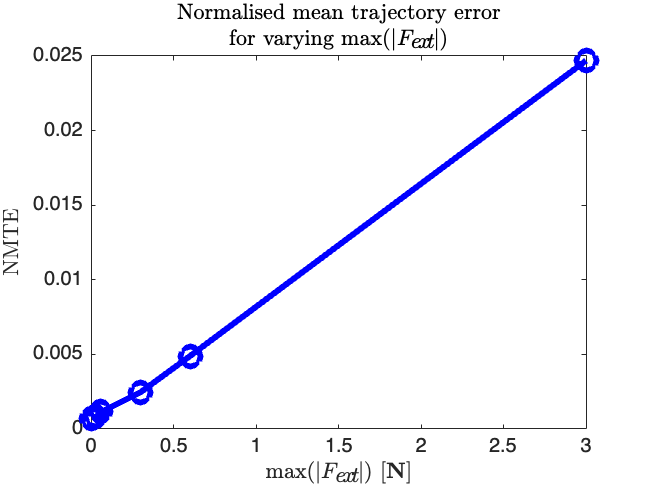

plot((m1+m2+Mf)*Epsilon,NMTET,'-o','MarkerSize',10,'LineWidth',3,'color','blue')
xlabel('max$(|F_{ext}|)$ [$\mathbf{N}$]','Interpreter','latex');
ylabel('NMTE','Interpreter','latex');
title({'Normalised mean trajectory error' 'for varying max$(|F_{ext}|)$'},'Interpreter','latex')

Full order model and reduced order model comparison:

F_I_net = [];

fig = figure

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


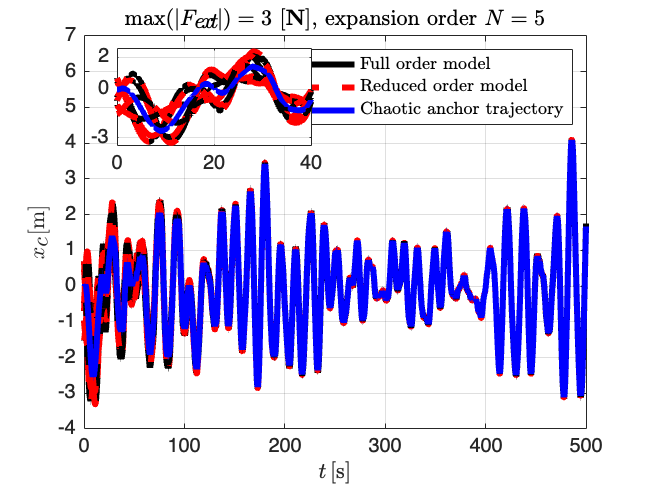

Elapsed time is 0.596614 seconds.


Elapsed time is 0.186073 seconds.


Elapsed time is 0.560346 seconds.


Elapsed time is 0.189575 seconds.


Elapsed time is 0.534063 seconds.


Elapsed time is 0.178185 seconds.


Elapsed time is 0.533344 seconds.


Elapsed time is 0.178368 seconds.


Elapsed time is 0.534375 seconds.


Elapsed time is 0.179640 seconds.


Elapsed time is 0.533419 seconds.


Elapsed time is 0.178368 seconds.


fontsize(fig, 20, "points")
set(gcf,'color','w');
box on
grid on ;
axis([0,500,-4,7])
ax1 = gca;
ax2 = axes( 'Position' ,[.18 .7 .3 .2]);
box on
grid on ;
NMTET = [];
% zo = [0.3*exp(-1i*pi/2),0.3*exp(1i*pi/2),0.5*exp(-1i*pi/2),0.5*exp(1i*pi/2),0.4*exp(1i*0.5),0.4*exp(-1i*0.5)];
zo = [1.2*exp(-1i*pi/2),1.2*exp(1i*pi/2),0.8*exp(-1i*pi/2),0.8*exp(1i*pi/2),1*exp(1i*0.5),1*exp(-1i*0.5)];

% zo = [6.2*exp(-1i*pi/2),1.2*exp(1i*pi/2),1*exp(-1i*pi/2),1*exp(1i*pi/2),0.8*exp(1i*0.5),0.1*exp(-1i*0.5)];

for ind = 1:6
epsilon = 0.5;

ROM_ODE_ns =@(t,zk) rom_temp_model_noscale(t,zk,l1,gamma,epsilon,xi_sol1,xi_sol3,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1);
ctspan = linspace(0,500,8000);

q0 = zo(ind);
y0 =compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,0,l1,l1,gamma,V,inv(V),q0,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);

IC = [real(q0);imag(q0)];

% IC = [1.2;0];
tic 
[t_sol,ROM_sol] = ode45(ROM_ODE_ns,ctspan,IC);
toc

lf = 0;
[y,modal] = compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,t_sol.',lf,ls,gamma,V,inv(V),(ROM_sol(:,1)+1i*ROM_sol(:,2)).',h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);




SolutionA = epsilon*xi_full_eval(ctspan.') +epsilon^3*xi_full_eval3(ctspan.')+epsilon^5*xi_full_eval5(ctspan.');
FullS = @(t,y) full_system(t,y,epsilon,Force_Lorenz,m1,m2,Mf,kf,k,c,cf,gamma);

tic
IC =  y0;
[tSP,SP_Traj] = ode45(FullS,ctspan,IC);
toc

F_an = (abs((m1+m2+Mf)*epsilon*Force_Lorenz(tSP))).';
% F_an = trapz(tSP,F_an)/(max(tSP)*mean(F_an));

F_spring = K*[y(1,:);y(2,:);y(3,:)];
F_damper = C*[y(4,:);y(5,:);y(6,:)];
F_nonlinear = [gamma*y(1,:).^3;0*y(1,:);0*y(1,:)];
F_total = F_spring + F_damper + F_nonlinear;
F_net = sqrt(sum(F_total.^2));
F_I_net = [F_I_net;trapz(tSP,F_an./F_net)/(max(tSP))];



 hold(ax1, 'on' );
indexR = 3;
plot(ax1,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
hold on 
plot(ax1,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
hold on 
plot(ax1,tSP,SolutionA(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3])
hold on 
xlabel(ax1,'$t \,[$s$]$','Interpreter','latex');
ylabel(ax1,'$x_{c} \,[$m$]$','Interpreter','latex');
legend(ax1,'Full order model','Reduced order model','Chaotic anchor trajectory','Interpreter','latex')
title(ax1,'max$(|F_{ext}|) = 3$ [$\mathbf{N}$], expansion order $N = 5$','Interpreter','latex')
% xticks(ax1,[0 20 40])
% yticks(ax1,[-4 0 3])

hold on

grid on ;

% ax2 = axes( 'Position' ,[.2 .7 .5 .2])
hold(ax2, 'on' );
hold on 
plot(ax2,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
hold on 
plot(ax2,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
hold on 
plot(ax2,tSP,SolutionA(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3])
hold on 
% xlabel(ax2,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax2,'$x_{c} \,[$m$]$','Interpreter','latex');
xticks(ax2,[0 20 40])
yticks(ax2,[-3 0 2])

axis([0,40,-3.5,2.5])
grid on ;

NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
NMTET = [NMTET,NMTE];
end

% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

NMTEavg = sum(NMTET)/6;

SSM snapshot

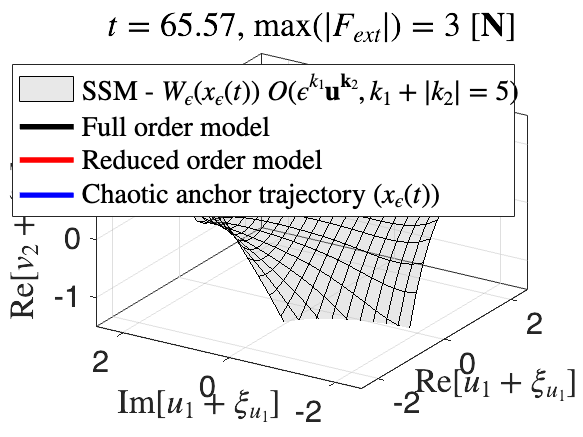

hFig = figure('DefaultAxesFontSize',18);                       % Bring up new figure
% imshow('board.tif','Border','tight') % The axes will fill up the entire figure as much as possible without changing aspect ratio.
% hFig.WindowState = 'maximized';
% pause(0.5)
delta = 0.5;
% tl =  100+2550;
tl = 50;
clear movieVector
shift_traj = y;
shift_trajZ = [real(modal(1,:));imag(modal(1,:));imag(modal(4,:));real(modal(3,:));real(modal(5,:))];%y;
ind = 1;
SP_TrajZ = inv(V)*SP_Traj.';
SP_TrajZ = [real(SP_TrajZ(1,:));imag(SP_TrajZ(1,:));imag(SP_TrajZ(4,:));real(SP_TrajZ(3,:));real(modal(5,:))];
SolutionZ = inv(V)*SolutionA.';
SolutionZ = [real(SolutionZ(1,:));imag(SolutionZ(1,:));imag(SolutionZ(4,:));real(SolutionZ(3,:));real(modal(5,:))];

Solution1 = SolutionA.';
SP_Traj1 = SP_Traj.';
nssm = 20;

for j =1000:1000% 150:2700 %2550:2550 %1000:1000 %150:150 %150:2700%2550 %1:20:5000%(max(size(t_sol))-tl)
i = j+0;

     clf
     rhosamp = linspace(0,0.5,201);
     plotdofs = [1 2 4]; 
     [RHO,Theta]=meshgrid(linspace(0,1,201),linspace(0,2*pi,201));
     x = linspace(-2,2,nssm);
     [X,Y]=meshgrid(x);
     Z = RHO.*exp(1i*Theta);
     Z = X+1i*Y;
     t_ssm = ones(1,nssm*nssm)*t_sol(j+tl);
     [ZZ,modalZ] = compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,t_ssm,l1,l1,gamma,V,inv(V),Z(:).',h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);
    
     Z1 = reshape(ZZ(1,:),nssm,nssm);
     Z2 = reshape(ZZ(2,:),nssm,nssm);
     Z3 = reshape(ZZ(3,:),nssm,nssm);


     starto = 1;
     Z1 = reshape(real(modalZ(1,:)),nssm,nssm);
     Z2 = reshape(imag(modalZ(1,:)),nssm,nssm);
     Z3 = reshape(real(modalZ(3,:)),nssm,nssm);

     h = surf(Z1,Z2,Z3);
     h.EdgeColor = 'k';
     h.FaceColor = [.7 .7 .7];
     h.FaceAlpha = 0.3;
     hold on 

     starto = 1;
     
     hold on
     plot3(SP_TrajZ(plotdofs(1),j:i+tl),SP_TrajZ(plotdofs(2),j:i+tl),SP_TrajZ(plotdofs(3),j:i+tl),'-','LineWidth',3,'Color',[0 0 0 0.5]);
     hold on
     plot3(shift_trajZ(plotdofs(1),j:i+tl),shift_trajZ(plotdofs(2),j:i+tl),shift_trajZ(plotdofs(3),j:i+tl),'-','LineWidth',3,'Color',[1,0,0,0.5]);
     hold on
     plot3(SolutionZ(plotdofs(1),j:i+tl),SolutionZ(plotdofs(2),j:i+tl),SolutionZ(plotdofs(3),j:i+tl),'-','LineWidth',3,'color',[0 0 1 0.5])
     hold on
      plot3(shift_trajZ(plotdofs(1),i+tl),shift_trajZ(plotdofs(2),i+tl),shift_trajZ(plotdofs(3),i+tl),'.','MarkerSize',30,'Color',[1,0,0]);
     hold on
     plot3(SP_TrajZ(plotdofs(1),i+tl),SP_TrajZ(plotdofs(2),i+tl),SP_TrajZ(plotdofs(3),i+tl),'.','MarkerSize',30,'Color','black');
     hold on
     plot3(SolutionZ(plotdofs(1),i+tl),SolutionZ(plotdofs(2),i+tl),SolutionZ(plotdofs(3),i+tl),'.','MarkerSize',30,'Color','blue');
     hold on
        
    xl = xlabel('Re[$u_1+\xi_{u_1}$]','Interpreter','latex');
     xl.Position = [-0.3395+2 -2.4427 -2.1373-0.3];
    xl.HorizontalAlignment = 'center';
    yl = ylabel('Im[$u_1+\xi_{u_1}$]','Interpreter','latex');
     yl.Position = [-2.3392 -0.6379+1.3 -1.9992-0.1];
    yl.HorizontalAlignment = 'center';
    zl = zlabel('Re[$v_2+\xi_{v_2}$]','Interpreter','latex');
    yticks([-2 0 2])

     
      legend('SSM - $W_{\epsilon}(x_{\epsilon}(t))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 5)$','Full order model','Reduced order model','Chaotic anchor trajectory ($x_{\epsilon}(t)$)','Interpreter','latex','location','northeast')

    string = strcat('$t = $',num2str(round(t_sol(j+tl),2),'%4.2f' ),', max$(|F_{ext}|) = 3$ [$\mathbf{N}$]');
    if (j+tl) >=3000
     string = strcat('{\color{blue}t = ',num2str(round(t_sol(j+tl),2),'%4.2f' ),',}\epsilon = 0.5');
     title(string);
    else
     title(string,'Interpreter','latex');
    end    
 view(-58,22)
    grid on
    box on 
     daspect([1,1,1])
   axis([-2.5,2.5,-2.5,2.5,-1.5,1.5])
set(gcf,'color','white')

set(gcf,'color','white')
set(hFig, 'Units' , 'Inches' );
pos = get(hFig, 'Position' );
set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
set(gcf,'Renderer','painters')

    figssm = gcf;

 movieVector(ind) = getframe(hFig);
    
    ind = ind +1;

end


% myWriter = VideoWriter('Shake_Cart_SSM_video_fast','MPEG-4');
% myWriter.FrameRate = 50;
% 
% open(myWriter);
% 
% for indj = 1:2551
% writeVideo(myWriter,movieVector(indj));
% end
% 
% close(myWriter);

% set(hFig, 'Units' , 'Inches' );
% pos = get(hFig, 'Position' );
% set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(hFig, 'ssm_shaking_cart_snap3.pdf' , '-dpdf' , '-r300' )

For $\epsilon = 0.01$ we compute the ratio of the trajectory averaged external and internal forces of the system.

% if flag == 1
F_I_net = [];
NMTET = [];
nssm = 30;
x = linspace(-2,2,nssm);
[X,Y]=meshgrid(x);
Z = X+1i*Y;
Ratio_Net = zeros(nssm,nssm);
Net1 = zeros(nssm,nssm);
Net2 = zeros(nssm,nssm);

accel = [];
for ind = 1:nssm
    for indk = 1:nssm
epsilon = 0.01;

 ctspan = linspace(0,500,8000);

 q0 = Z(ind,indk);
 y0 =compute_SSM_phy(xi_full_eval5,xi_full_eval3,xi_full_eval,0,l1,l1,gamma,V,inv(V),q0,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1,h500,h050,h320,h230,h410,h140,f500,f050,f320,f230,f410,f140,H_Coeff2,F_Coeff2,epsilon);

 IC = [real(q0);imag(q0)];

 FullS = @(t,y) full_system(t,y,0,Force_Lorenz,m1,m2,Mf,kf,k,c,cf,gamma);

 tic
 IC =  y0;
 [tSP,SP_Traj] = ode45(FullS,ctspan,IC);
 toc

 y = SP_Traj.';
 F_an = (abs((m1+m2+Mf)*epsilon*Force_Lorenz(tSP))).';

 F_spring = K*[y(1,:);y(2,:);y(3,:)];
 F_damper = C*[y(4,:);y(5,:);y(6,:)];
 F_nonlinear = [gamma*y(1,:).^3;0*y(1,:);0*y(1,:)];
 F_total = F_spring + F_damper + F_nonlinear;
 F_net = sqrt(sum(F_total.^2));
 F_I_net = [F_I_net;trapz(tSP,F_an./F_net)/(max(tSP))];
 Net1(ind,indk) = trapz(tSP,F_an)/(max(tSP));
 Net2(ind,indk) = (trapz(tSP,F_net)/(max(tSP)));
 Ratio_Net(ind,indk) = trapz(tSP,F_an)/(max(tSP))./(trapz(tSP,F_net)/(max(tSP)));

 F_spring = inv(M)*K*[y(1,:);y(2,:);y(3,:)];
 F_damper = inv(M)*C*[y(4,:);y(5,:);y(6,:)];
 F_nonlinear = inv(M)*[gamma*y(1,:).^3;0*y(1,:);0*y(1,:)];
 F_total = F_spring + F_damper + F_nonlinear;
 F_net = sqrt(sum(F_total.^2));
 accel = [accel,F_net];


% NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
% NMTET = [NMTET,NMTE];
    end
end

Elapsed time is 0.108265 seconds.
Elapsed time is 0.136267 seconds.
Elapsed time is 0.138937 seconds.
Elapsed time is 0.135303 seconds.
Elapsed time is 0.127495 seconds.
Elapsed time is 0.129672 seconds.
Elapsed time is 0.127446 seconds.
Elapsed time is 0.126323 seconds.
Elapsed time is 0.125238 seconds.
Elapsed time is 0.130322 seconds.
Elapsed time is 0.129629 seconds.
Elapsed time is 0.126797 seconds.
Elapsed time is 0.124977 seconds.
Elapsed time is 0.131672 seconds.
Elapsed time is 0.134269 seconds.
Elapsed time is 0.130578 seconds.
Elapsed time is 0.128734 seconds.
Elapsed time is 0.127584 seconds.
Elapsed time is 0.127566 seconds.
Elapsed time is 0.128622 seconds.
Elapsed time is 0.132137 seconds.
Elapsed time is 0.137996 seconds.
Elapsed time is 0.136510 seconds.
Elapsed time is 0.127382 seconds.
Elapsed time is 0.125637 seconds.
Elapsed time is 0.129160 seconds.
Elapsed time is 0.126866 seconds.
Elapsed time is 0.126807 seconds.
Elapsed time is 0.132035 seconds.
Elapsed time i

bp = mean( Net1(:))./mean( Net2(:));
flag = [abs(sqrt(X.^2 + Y.^2)) < 0.3];
Ratio_Net(flag)= NaN;
NMTEavg = sum(NMTET)/6;
fig = figure

fig =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


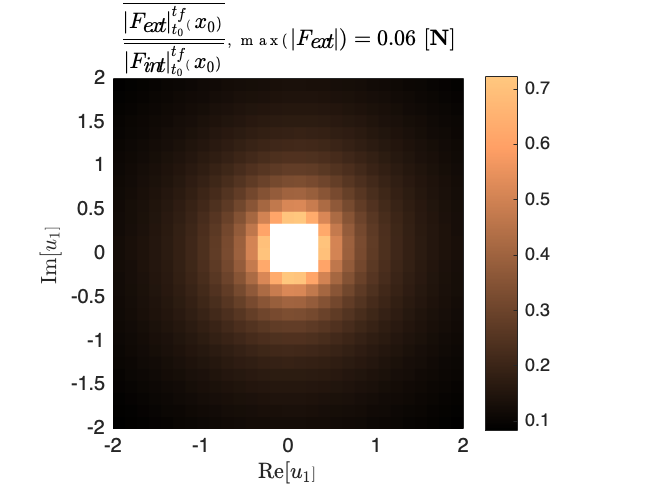

P = pcolor(X,Y,Ratio_Net);
P.EdgeColor = 'none';
colormap copper
colorbar 
xlabel('Re[$u_1$]','Interpreter','latex');
ylabel('Im[$u_1$]','Interpreter','latex');
title_string = strcat('$\displaystyle \frac{\overline{|F_{ext}|_{t_0}^{t_f}(x_0)}}{\overline{|F_{int}|_{t_0}^{t_f}(x_0)}}$, max$(|F_{ext}|) = ',num2str((m1+m2+Mf)*epsilon),'$ [$\mathbf{N}$]');
daspect([1 1 1])
title(title_string,'Interpreter','latex')

impratio = epsilon/max(accel);
save('Mean_force_ratio.mat','bp');
% end
load('Mean_force_ratio.mat','bp');
disp(['Mean ratio of external and internal forces = ',num2str(bp)]);

Mean ratio of external and internal forces = 0.15653
